%Transit time(TIme taken to attain steady state/time steps(in this
%context))
%context)) is high for fully subsonic flow because flow speed is slow.
clc;
clear all;
prompt=input('Enter either 1/2?');%1-Subsonic-Supersonic flow in CD nozzle,2-Fully Subsonic flow in CD Nozzle
choice=prompt;
x=linspace(0,3,31);%No of grid points taken is 31
C=0.5;%Courant No
t=0;
d1=digits;
digits(4);
for i=1:31%Initial boundary conditions for both cases
  if choice==1 
    A(i)=1+2.2*((x(i)-1.5)^2);
    D(i)=1-0.3146*x(i);
    T(i)=1-0.2314*x(i);
    V(i)=(0.1+1.09*x(i))*sqrt(T(i));
    p(i)=D(i)*T(i);
  else
    if i<16 || i==16
         A(i)=1+2.2*((x(i)-1.5)^2);
    else
         A(i)=1+0.2223*((x(i)-1.5)^2);
    end
    D(i)=1-0.023*x(i);
    T(i)=1-0.009333*x(i);
    V(i)=(0.05+.11*x(i));
    p(i)=D(i)*T(i);
  end

end
Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p)];
disp(Net);

         0    5.9500    1.0000    0.1000    1.0000    1.0000
    0.1000    5.3120    0.9685    0.2066    0.9769    0.9461
    0.2000    4.7180    0.9371    0.3106    0.9537    0.8937
    0.3000    4.1680    0.9056    0.4119    0.9306    0.8428
    0.4000    3.6620    0.8742    0.5106    0.9074    0.7932
    0.5000    3.2000    0.8427    0.6065    0.8843    0.7452
    0.6000    2.7820    0.8112    0.6997    0.8612    0.6986
    0.7000    2.4080    0.7798    0.7900    0.8380    0.6535
    0.8000    2.0780    0.7483    0.8774    0.8149    0.6098
    0.9000    1.7920    0.7169    0.9619    0.7917    0.5676
    1.0000    1.5500    0.6854    1.0433    0.7686    0.5268
    1.1000    1.3520    0.6539    1.1216    0.7455    0.4875
    1.2000    1.1980    0.6225    1.1967    0.7223    0.4496
    1.3000    1.0880    0.5910    1.2685    0.6992    0.4132
    1.4000    1.0220    0.5596    1.3369    0.6760    0.3783
    1.5000    1.0000    0.5281    1.4019    0.6529    0.3448
    1.6000    1.0220    

for i=1:31
    del_t(i)=C*(0.1/((T(i)^0.5)+V(i)));
end
t_step=min(del_t);
count=2;
timestep(1)=0;
density(1)=D(16);
while(t<200)
 [dD_dt,dT_dt,dV_dt,D_p,T_p,V_p]=predictor(A,D,T,V,t_step);%Predictor Step where forward differencing is used
 [dD_dt1,dT_dt1,dV_dt1]=corrector(A,D_p,T_p,V_p);%Corrector step where rearward differencing used
 dD_dtavg=(dD_dt+dD_dt1)/2;
 dT_dtavg=(dT_dt+dT_dt1)/2;
 dV_dtavg=(dV_dt+dV_dt1)/2;
 M(1)=0;
 a(1)=0;
 
 for i=2:30
  D(i)=D(i)+dD_dtavg(i)*t_step;
  T(i)=T(i)+dT_dtavg(i)*t_step;
  V(i)=V(i)+dV_dtavg(i)*t_step;
  a(i)=T(i)^0.5;
  M(i)=V(i)/a(i);
  p(i)=D(i)*T(i);
 end
if choice==1 
  V(1)=2*V(2)-V(3);
  V(31)=2*V(30)-V(29);
  D(31)=2*D(30)-D(29);
  T(31)=2*T(30)-T(29);
  a(1)=T(1)^0.5;
  a(31)=T(31)^0.5;
  M(1)=V(1)/a(1);
  M(31)=V(31)/a(31);
 
  p(31)=D(31)*T(31);
  Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T)  transpose(p) transpose(M) ];
  disp(Net);
  t=t+t_step;
  timestep(count)=t;
  density(count)=D(16);
  
else
  p(31)=0.93;%If pe/po =0.93 solution is stable for fully subsonic flow but if pe/po=o.904 as per initial conditions,then the solution blows up and is unstable.   
  V(1)=2*V(2)-V(3);
  V(31)=2*V(30)-V(29);
  D(31)=2*D(30)-D(29);
  T(31)=p(31)/D(31);
  a(1)=T(1)^0.5;
  a(31)=T(31)^0.5;
  M(1)=V(1)/a(1);
  M(31)=V(31)/a(31);
 
  
  Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T)  transpose(p) transpose(M) ];
  disp(Net);
  t=t+t_step;
  timestep(count)=t;
  density(count)=D(16);  


end
count=count+1;
end

         0    5.9500    1.0000    0.1111    1.0000    1.0000    0.1111
    0.1000    5.3120    0.9541    0.2114    0.9714    0.9269    0.2145
    0.2000    4.7180    0.9269    0.3117    0.9502    0.8808    0.3197
    0.3000    4.1680    0.8995    0.4112    0.9289    0.8356    0.4267
    0.4000    3.6620    0.8721    0.5083    0.9076    0.7915    0.5335
    0.5000    3.2000    0.8445    0.6028    0.8862    0.7484    0.6403
    0.6000    2.7820    0.8167    0.6946    0.8648    0.7063    0.7469
    0.7000    2.4080    0.7887    0.7838    0.8434    0.6651    0.8535
    0.8000    2.0780    0.7602    0.8703    0.8217    0.6247    0.9601
    0.9000    1.7920    0.7312    0.9540    0.7998    0.5848    1.0667
    1.0000    1.5500    0.7012    1.0349    0.7775    0.5452    1.1736
    1.1000    1.3520    0.6701    1.1128    0.7547    0.5057    1.2810
    1.2000    1.1980    0.6374    1.1878    0.7313    0.4661    1.3890
    1.3000    1.0880    0.6031    1.2597    0.7070    0.4264    1.4982
    1.

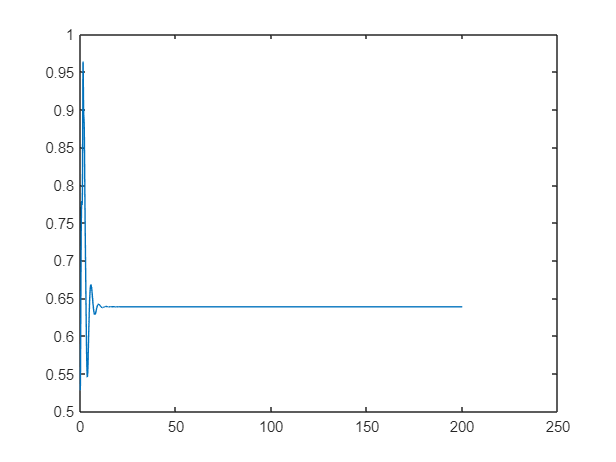

plot(timestep,density);

function [d,t,v,d1,t1,v1]=predictor(A,D,T,V,t_step)
  d1(1)=1;
  t1(1)=1;
  v1(1)=V(1);
  for i=2:30
     dV_dx= (V(i+1)-V(i))/0.1;
     dA_dx= (log(A(i+1))-log(A(i)))/0.1;
     dD_dx=(D(i+1)-D(i))/0.1;
     dT_dx=(T(i+1)-T(i))/0.1;
     d(i)=-(D(i)*dV_dx)-(D(i)*V(i)*dA_dx)-(V(i)*dD_dx);
     v(i)=-(V(i)*dV_dx)-0.714*(dT_dx+(dD_dx*T(i)/D(i)));
     t(i)=-(V(i)*dT_dx)-0.4*T(i)*(dV_dx+V(i)*dA_dx);
     d1(i)=D(i)+d(i)*t_step;
     t1(i)=T(i)+t(i)*t_step;
     v1(i)=V(i)+v(i)*t_step;
     
  end
  d1(31)=D(31);
  t1(31)=T(31);
  v1(31)=V(31);
end

function [d,t,v]=corrector(A,D,T,V)
 
  for i=2:30
     dV_dx= (V(i)-V(i-1))/0.1;
     dA_dx= (log(A(i))-log(A(i-1)))/0.1;
     dD_dx=(D(i)-D(i-1))/0.1;
     dT_dx=(T(i)-T(i-1))/0.1;
     d(i)=-(D(i)*dV_dx)-(D(i)*V(i)*dA_dx)-(V(i)*dD_dx);
     v(i)=-(V(i)*dV_dx)-0.714*(dT_dx+(dD_dx*T(i)/D(i)));
     t(i)=-(V(i)*dT_dx)-0.4*T(i)*(dV_dx+V(i)*dA_dx);
     

  end
end






